# Paired-Sample T-Test Example

Babak Aliyari

Babak.aliyari.edu@gmail.com

#### **Define Hypotheses for Paired T-Test:**

#### **Null Hypothesis (H0): μ_difference = 0 (No significant difference between pre and post) **

#### **Alternative Hypothesis (H1): μ_difference ≠ 0 (Significant difference between pre and post scores)**

clear all;
close all;
clc;
cd('D:\0 Signal\AmarT');
% Simulate pre-post intervention data
rng(25); % Set seed for reproducibility
n = 30; % Number of subjects
preScores = 60 + 10 * randn(n, 1); % Baseline scores
treatmentEffect = 5 + 3 * randn(n, 1); % Variable treatment effect
postScores = preScores + treatmentEffect; % Post-treatment scores

% Perform paired T-test
[h, p, ci, stats] = ttest(preScores, postScores);

% Display results
fprintf('\nPaired-Sample T-Test Results:\n');


Paired-Sample T-Test Results:


fprintf('Pre-test mean: %.2f, Post-test mean: %.2f\n', mean(preScores), mean(postScores));

Pre-test mean: 59.39, Post-test mean: 64.66


fprintf('Mean difference: %.2f\n', mean(postScores - preScores));

Mean difference: 5.27


fprintf('t-statistic: %.4f\n', stats.tstat);

t-statistic: -10.2306


fprintf('Degrees of freedom: %d\n', stats.df);

Degrees of freedom: 29


fprintf('p-value: %.6f\n', p);

p-value: 0.000000


fprintf('95%% Confidence Interval for difference: [%.2f, %.2f]\n', ci(1), ci(2));

95% Confidence Interval for difference: [-6.32, -4.22]



% Interpret results
if h == 1
    fprintf('Conclusion: Reject H0 - Significant difference between paired observations\n');
else
    fprintf('Conclusion: Fail to reject H0 - No significant difference between paired observations\n');
end

Conclusion: Reject H0 - Significant difference between paired observations


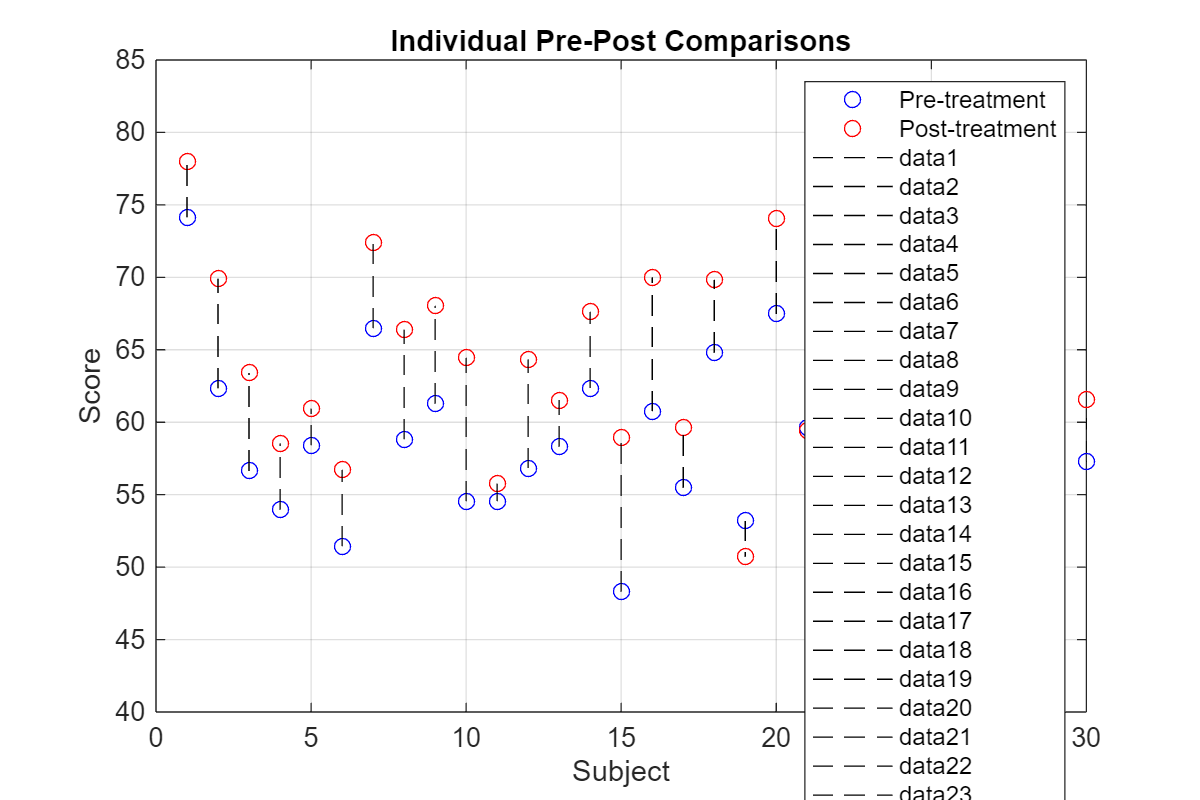


% Figure 1: Individual Pre-Post Comparisons
figure('Name', 'Individual Pre-Post Comparisons', 'Position', [100, 100, 600, 400]);
plot(1:n, preScores, 'bo', 1:n, postScores, 'ro');
legend('Pre-treatment', 'Post-treatment');
xlabel('Subject');
ylabel('Score');
title('Individual Pre-Post Comparisons');
hold on;
for i = 1:n
    plot([i, i], [preScores(i), postScores(i)], 'k--');
end
hold off;
grid on;

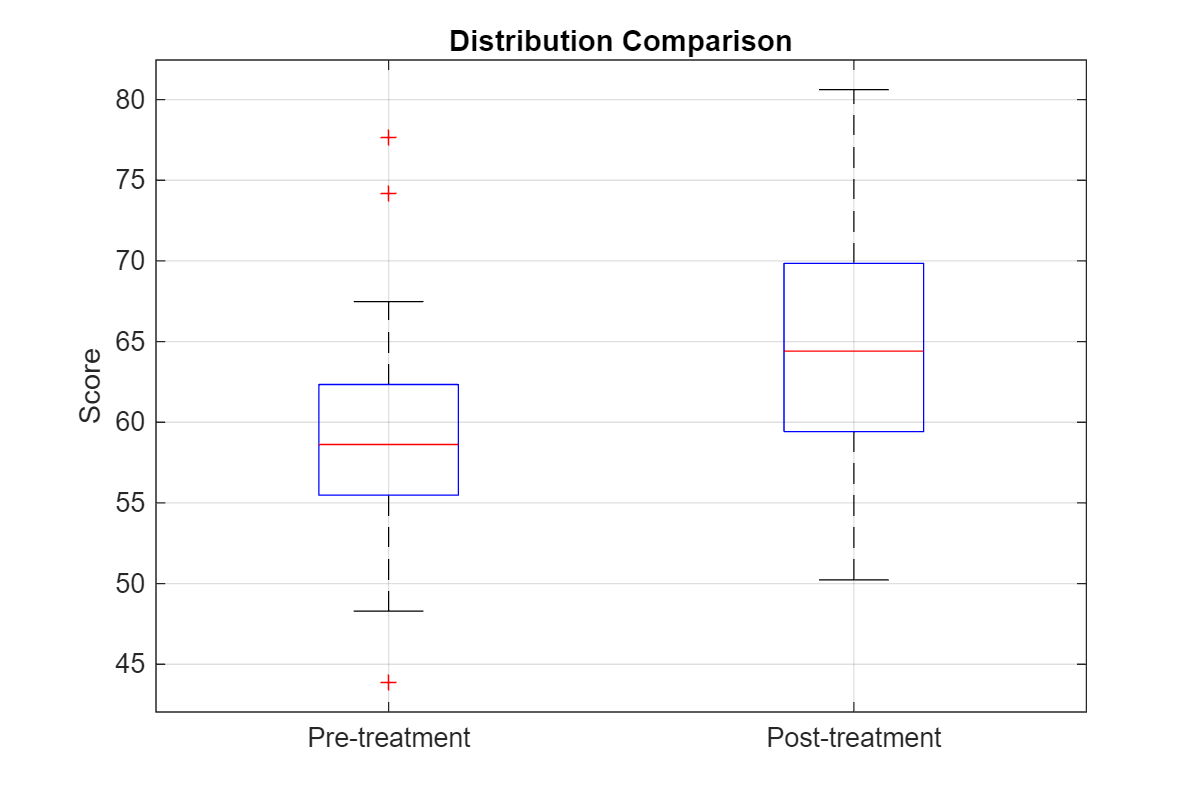


% Figure 2: Distribution Comparison
figure('Name', 'Distribution Comparison', 'Position', [200, 200, 600, 400]);
boxplot([preScores, postScores], 'Labels', {'Pre-treatment', 'Post-treatment'});
ylabel('Score');
title('Distribution Comparison');
grid on;

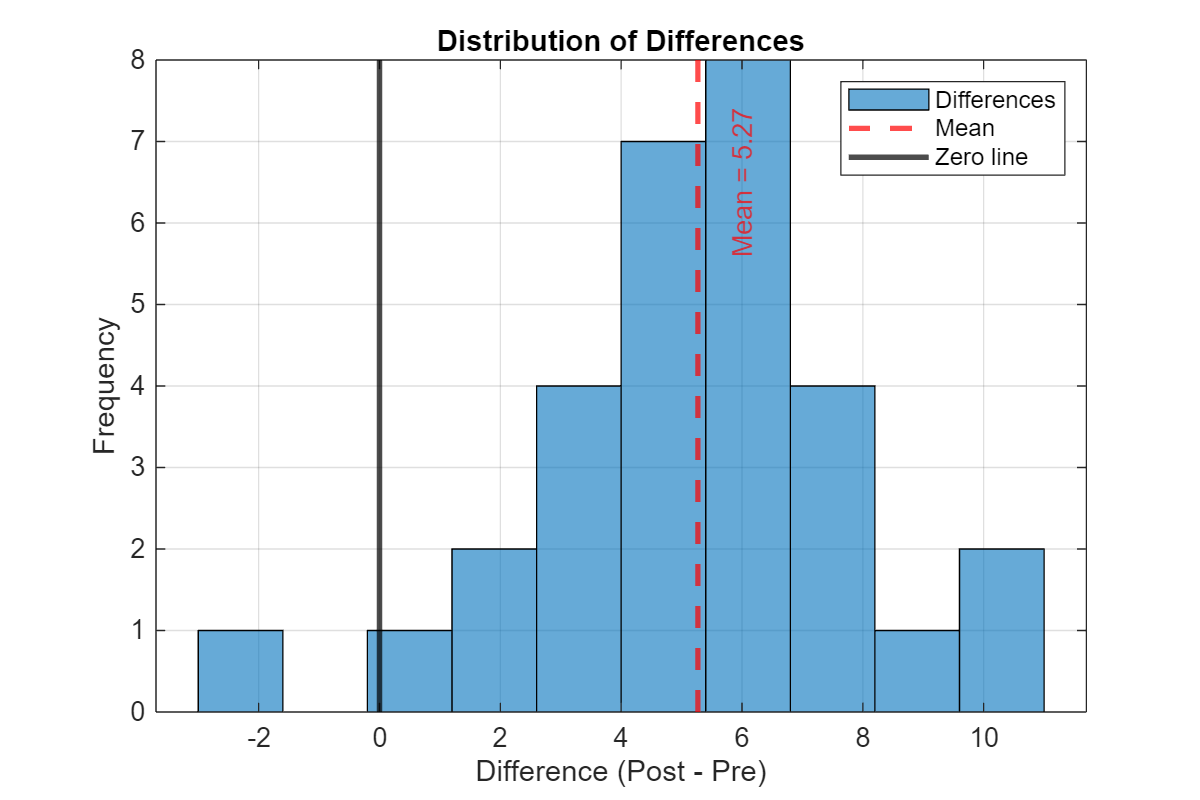


% Figure 3: Distribution of Differences
figure('Name', 'Distribution of Differences', 'Position', [300, 300, 600, 400]);
differences = postScores - preScores;
histogram(differences, 10);
xlabel('Difference (Post - Pre)');
ylabel('Frequency');
title('Distribution of Differences');
hold on;
xline(mean(differences), 'r--', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean(differences)));
xline(0, 'k-', 'LineWidth', 2);
legend('Differences', 'Mean', 'Zero line');
grid on;

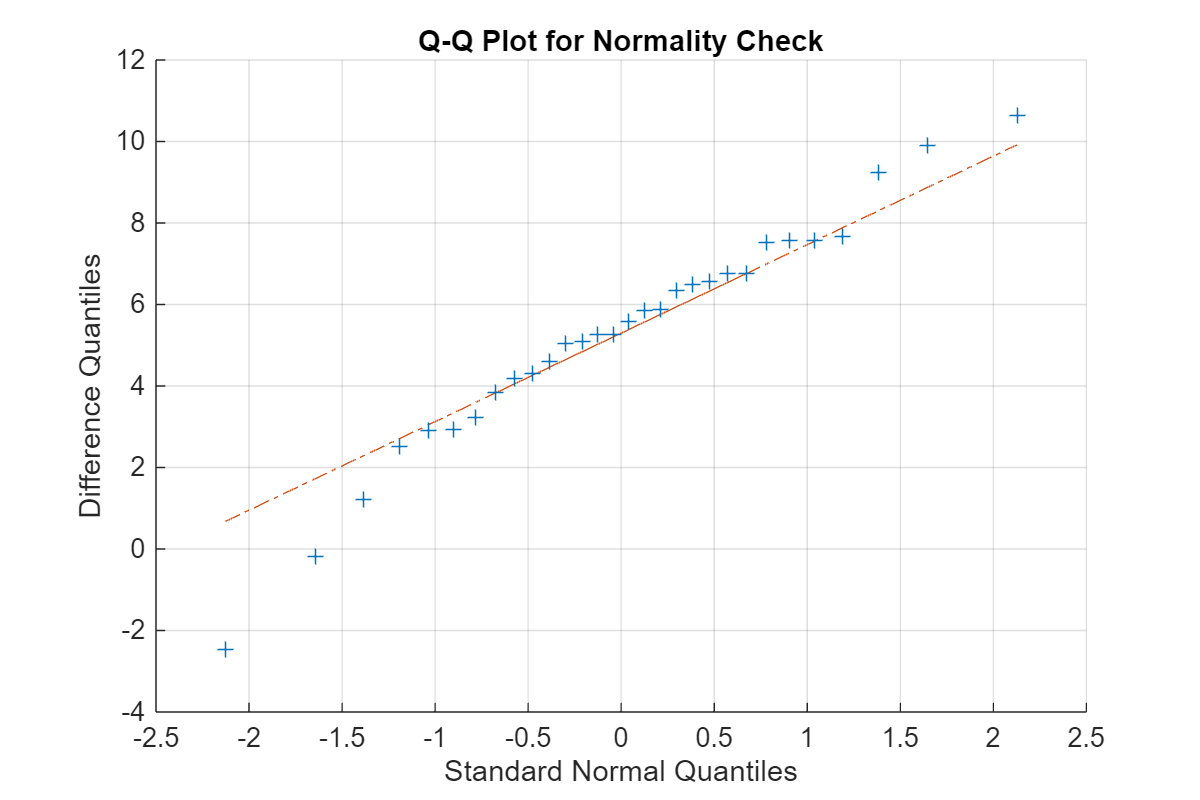


% Figure 4: Q-Q Plot for Normality Check
figure('Name', 'Q-Q Plot for Normality Check', 'Position', [400, 400, 600, 400]);
qqplot(differences);
title('Q-Q Plot for Normality Check');
ylabel('Difference Quantiles');
grid on;

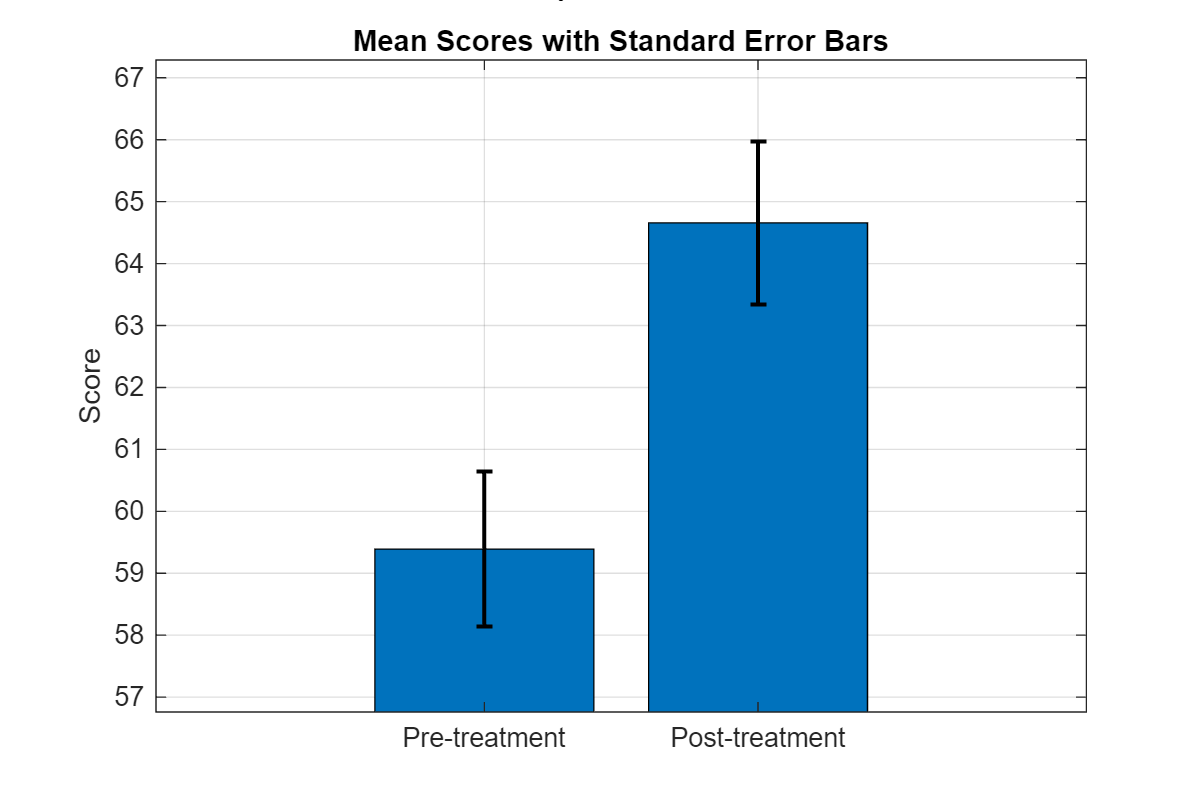


% Figure 5: Mean Scores with Standard Error Bars
figure('Name', 'Mean Scores with Standard Error Bars', 'Position', [500, 500, 600, 400]);
means = [mean(preScores), mean(postScores)];
sems = [std(preScores)/sqrt(n), std(postScores)/sqrt(n)]; % Standard error of the mean

bar(means, 'FaceColor', 'flat');
hold on;
er = errorbar(1:2, means, sems, sems);
er.Color = [0 0 0];
er.LineStyle = 'none';
er.LineWidth = 1.5;

set(gca, 'XTickLabel', {'Pre-treatment', 'Post-treatment'});
ylabel('Score');
title('Mean Scores with Standard Error Bars');
ylim([min(means)-2*max(sems) max(means)+2*max(sems)]);

% Add significance bar if significant
if h == 1
    max_y = max(means + sems) + 2;
    plot([1 2], [max_y max_y], 'k-', 'LineWidth', 1.5);
    text(1.5, max_y + 0.5, sprintf('p = %.4f', p), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

hold off;
grid on;